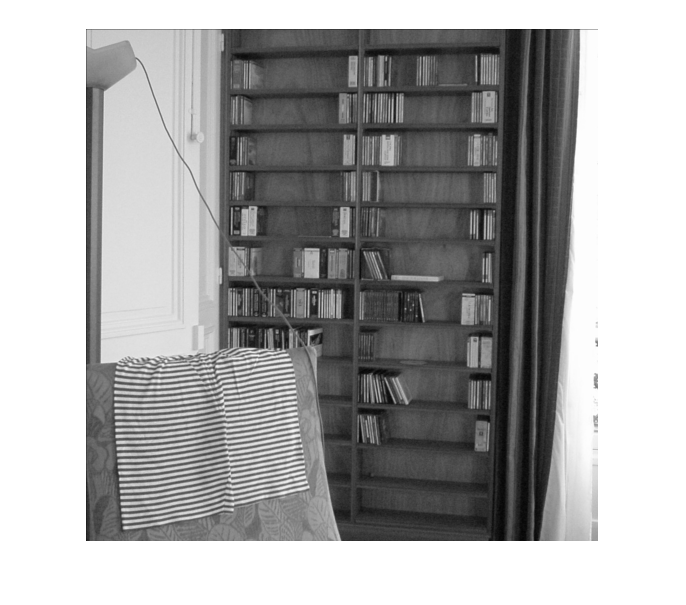

u = double(imread('room.pgm'))/255;
imshow(u);

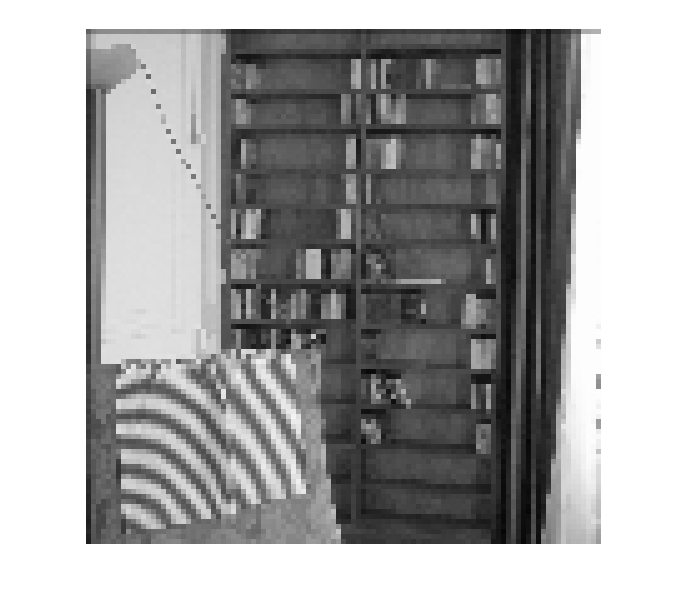

% the following code samples the image 
% then make each pixel 
% lambda times larger
lambda =5;
v = u(1:lambda:end,1:lambda:end);
w = kron(v,ones(lambda));
[ny,nx] = size(u);
imshow(w);

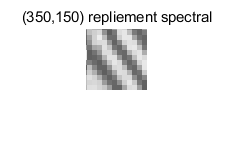

% Question 2
figure;
imshow(w(340:400,140:200));
title("(350,150) repliement spectral");

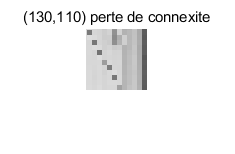

figure;
imshow(w(100:160,80:140));
title("(130,110) perte de connexite");

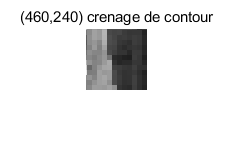

figure;
imshow(w(420:480,220:280));
title("(460,240) crenage de contour");

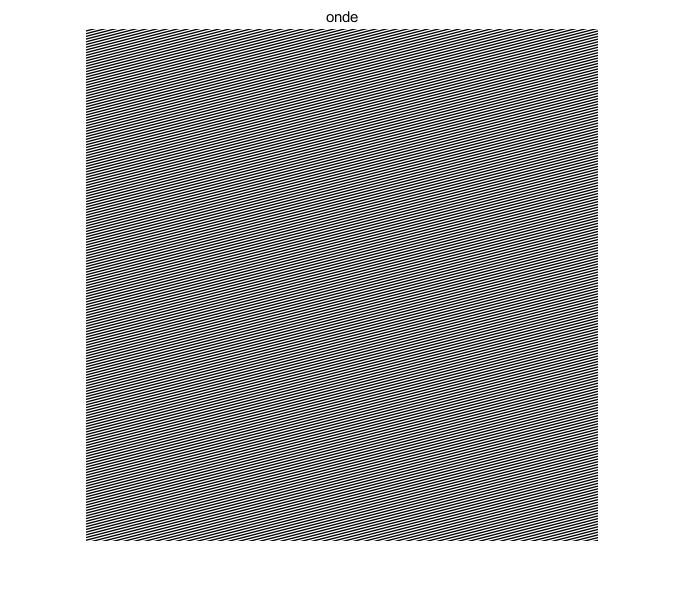

% Question 3
f = zeros(512);
f(190,50) = 2;
onde = real(ifft2(f))+0.01;
figure;
imshow(onde,[]);
title('onde')

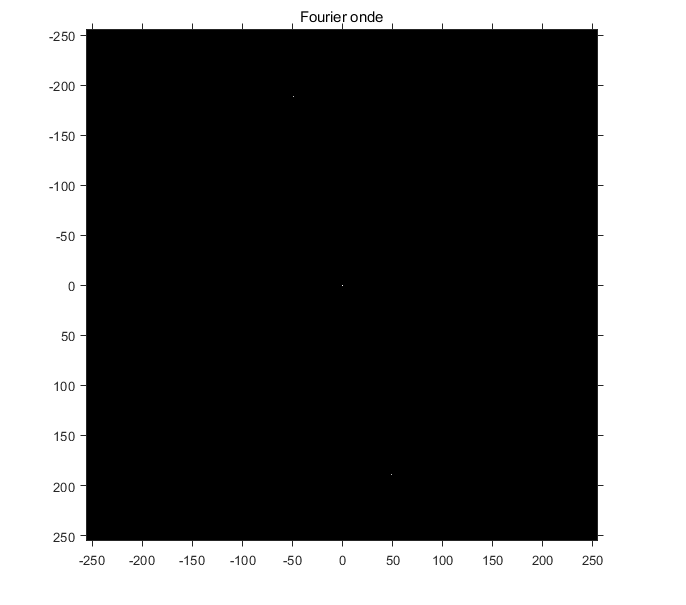

F_onde = abs(fftshift(fft2(onde)));
a=-256;b=255;
figure;
imshow(log(F_onde+1e-10),[],'xdata',a:b,'ydata',a:b);
axis on;
title('Fourier onde');


F_onde = ifftshift(F_onde);
F_onde(1,1)=0;% kill the largest point
[~,pos]=max(F_onde(:));
[x,y] = ind2sub(size(F_onde),pos);
[x-1,y-1]

ans =    189    49


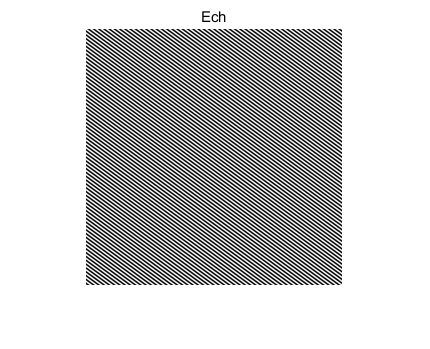


ech = onde(1:2:end,1:2:end);
figure;
imshow(ech,[]);
title('Ech');

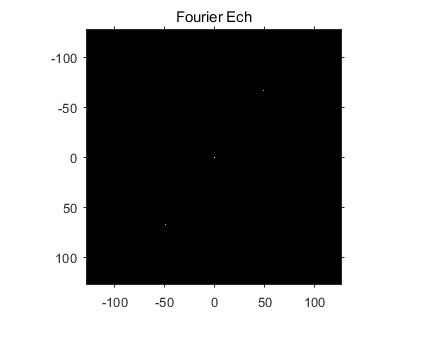


figure;
F_ech = abs(fftshift(fft2(ech)));
a=-128;b=127;
imshow(log(F_ech+1e-10),[],'xdata',a:b,'ydata',a:b);
axis on;
title('Fourier Ech');


F_ech = ifftshift(F_ech);
F_ech(1,1)=0;% kill the largest point
[~,pos]=max(F_ech(:));
[x,y] = ind2sub(size(F_ech),pos);
[x-1,y-1]

ans =    189    49


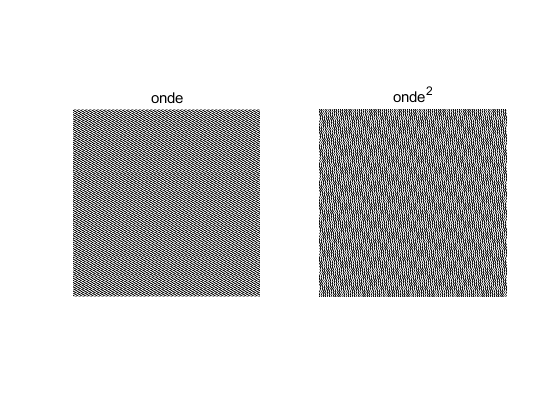

% Exo 5 Question 1
f = zeros(512);
f(100,50) = 2;
onde = real(ifft2(f));
figure;
subplot(1,2,1);
imshow([onde],[]);
title('onde')
subplot(1,2,2);
imshow([onde.^2],[]);
title('onde^2')


$$\widehat{f \cdot f} = \hat{f} * \hat{f}$$


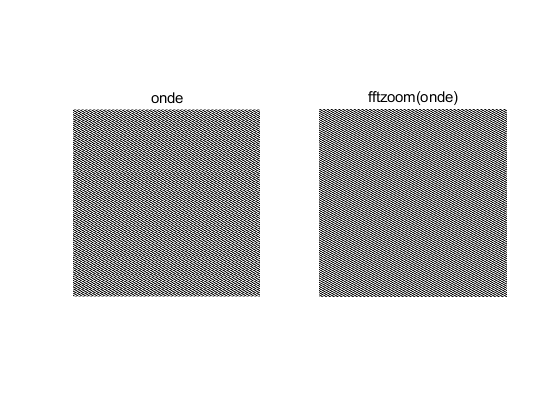

onde_zoom = fftzoom(onde,2);
figure;
subplot(1,2,1);
imshow([onde],[]);
title('onde')
subplot(1,2,2);
imshow([onde_zoom],[]);
title('fftzoom(onde)')